# Acceptance-Rejection Methods

The functional form of some distributions makes it difficult or time-consuming to generate random numbers using direct or inversion methods. Acceptance-rejection methods provide an alternative in these cases.

Acceptance-rejection methods begin with uniform random numbers, but require an additional random number generator. If your goal is to generate a random number from a continuous distribution with pdf $f$, acceptance-rejection methods first generate a random number from a continuous distribution with pdf $g$ satisfying $f(x) \leq cg(x)$ for some $c$ and all $x$.

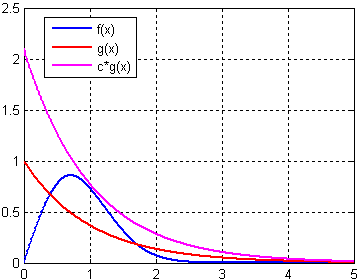

A continuous acceptance-rejection RNG proceeds as follows:

- Chooses a density $g$.

- Finds a constant $c$ such that $f(x)/g(x) \leq c$ for all $x$.

- Generates a uniform random number $u$.

- Generates a random number $v$ from $g$.

- If $cu \leq f(v)/g(v)$, accepts and returns $v$. Otherwise, rejects $v$ and goes to step 3.

For efficiency, a "cheap" method is necessary for generating random numbers from $g$, and the scalar $c$ should be small. The expected number of iterations to produce a single random number is $c$.

The following function implements an acceptance-rejection method for generating random numbers from pdf $f$ given $f$, $g$, the RNG `grnd` for $g$, and the constant $c$:

For example, the function $f(x) = xe^{-x^{2}/2}$ satisfies the conditions for a pdf on $[0,\infty)$ (nonnegative and integrates to 1). The exponential pdf with mean 1, $f(x) = e^{-x}$, dominates $g$ for $c$ greater than about 2.2. Thus, you can use [`rand`](docid:matlab_ref.buiavoq-1) and [`exprnd`](docid:stats_ug.brx09qp-693) to generate random numbers from $f$:

f = @(x)x.*exp(-(x.^2)/2);
g = @(x)exp(-x);
grnd = @()exprnd(1);
rng('default') % For reproducibility
X = accrejrnd(f,g,grnd,2.2,1e4,1);

The pdf $f$ is actually a [Rayleigh Distribution](docid:stats_ug.brn2ivz-132) with shape parameter 1. This example compares the distribution of random numbers generated by the acceptance-rejection method with those generated by [`raylrnd`](docid:stats_ug.f1131804):

Y = raylrnd(1,1e4,1); 
histogram(X)
hold on
histogram(Y)
legend('A-R RNG','Rayleigh RNG')

The `raylrnd` function uses a transformation method, expressing a Rayleigh random variable in terms of a chi-square random variable, which you compute using [`randn`](docid:matlab_ref.bufqhx9).

Acceptance-rejection methods also work for discrete distributions. In this case, the goal is to generate random numbers from a distribution with probability mass $P_p(X = i) = p_i$, assuming that you have a method for generating random numbers from a distribution with probability mass $P_q(X = i) = q_i$. The RNG proceeds as follows:

- Chooses a density $P_q$.

- Finds a constant $c$ such that $p_i/q_i \leq c$ for all $i$.

- Generates a uniform random number $u$.

- Generates a random number $v$ from $P_q$.

- If $cu \leq p_v/q_v$, accepts and returns $v$. Otherwise, rejects $v$ and goes to step 3.

*Copyright 2012 The MathWorks, Inc.*